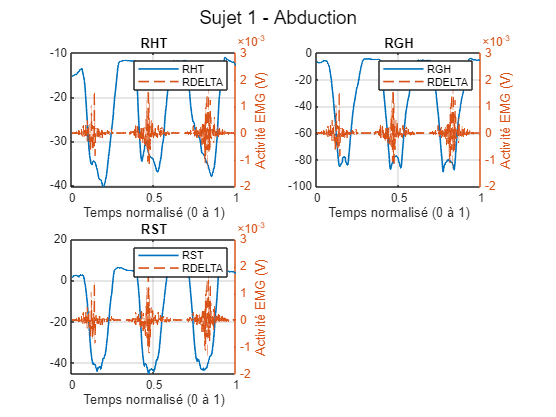

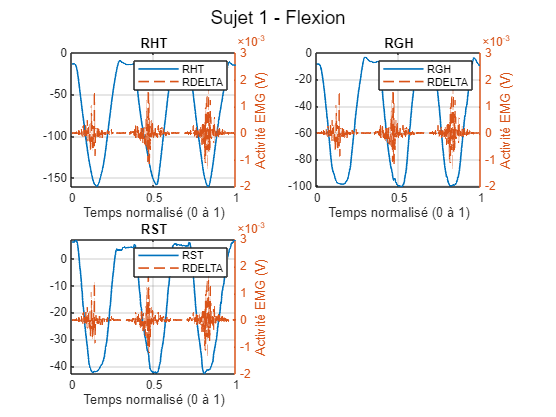

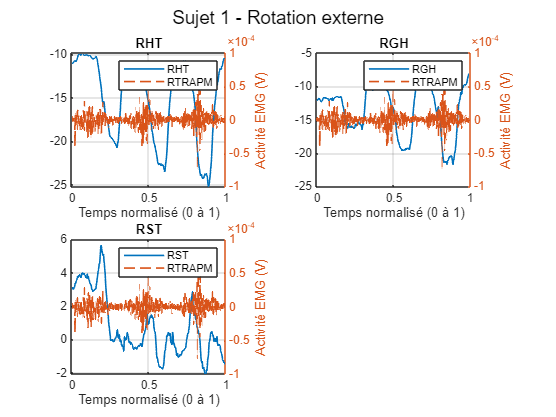

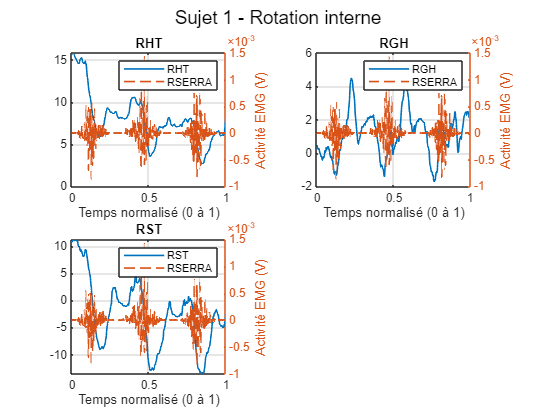

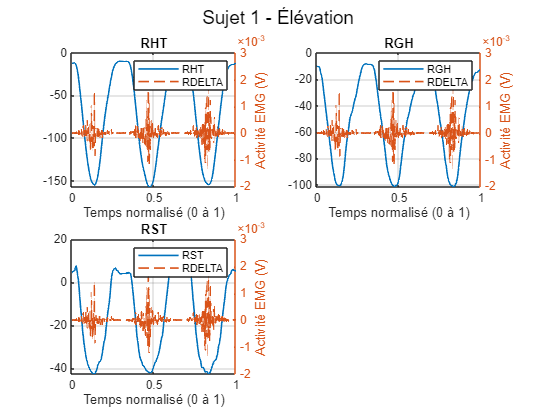

%% Ajout de la bibliothèque btk 
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

%% Définition des paramètres
subjects = {'MF01'};
nb_subjects = length(subjects);

muscles_mapping = containers.Map({...
    'Flexion', 'Abduction', 'Élévation', 'Rotation externe', 'Rotation interne' ...
}, {...
    'RDELTA', 'RDELTA', 'RDELTA', 'RTRAPM', 'RSERRA' ...
});

analytic_labels = keys(muscles_mapping);
nb_analytics = length(analytic_labels);

fs = 2000; % Fréquence d'échantillonnage
[b, a] = butter(4, [15, 475] / (fs/2), 'bandpass'); % Filtre Butterworth passe-bande
rms_window = round(0.250 * fs); % Fenêtre Root Mean Square
num_points = 1000; % Normalisation du temps sur 1000 points
time_normalized = linspace(0, 1, num_points);

matFiles = {...  
    'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets\MF01\MF01-MF01-20240101-20240710.mat' ...
};

joints = {'RHT', 'RGH', 'RST'};
% RHT : Humérus droit par rapport au tronc (Right Humerus to Trunk)
% RGH : Scapula droite par rapport au thorax (Right Glenohumeral joint)
% RST : Sternum par rapport au tronc (Right Sternum to Trunk)
nb_joints = length(joints);

%% Boucle sur chaque sujet
for subj_idx = 1:length(matFiles)
    % Charger les données du sujet
    base = load(matFiles{subj_idx});
    data = base.Trial;

    % Boucle sur chaque analytic
    for a_idx = 1:nb_analytics
        analytic_label = analytic_labels{a_idx};
        muscle_name = muscles_mapping(analytic_label);
        analytic_data = data(a_idx + 3);
        joint_data = analytic_data.Joint;
        
        figure;
        sgtitle(sprintf('Sujet %d - %s', subj_idx, analytic_label));
        
        % Tracé des angles avec overlay du muscle pertinent
        for i = 1:nb_joints
            joint_name = joints{i};
            joint_idx = find(strcmp({joint_data.label}, joint_name));
            if isempty(joint_idx), continue; end
            if isfield(joint_data(joint_idx), 'Euler') && isfield(joint_data(joint_idx).Euler, 'full')
                euler_data = joint_data(joint_idx).Euler.full;
                if size(euler_data, 1) == 1 && size(euler_data, 2) == 3 && size(euler_data, 3) > 1
                    kin = squeeze(euler_data(1, 1, :));
                    time_original = linspace(0, 1, length(kin));
                    kin_interp = interp1(time_original, kin, time_normalized, 'spline');
                    
                    subplot(ceil(nb_joints/2), 2, i);
                    plot(time_normalized, kin_interp, 'LineWidth', 1.2, 'DisplayName', joint_name);
                    hold on;
                    
                    % Ajout de l'EMG du muscle correspondant
                    if isfield(analogs, muscle_name)
                        signal = analogs.(muscle_name);
                        signal_interp = interp1(linspace(0, 1, length(signal)), signal, time_normalized, 'spline');
                        yyaxis right;
                        plot(time_normalized, signal_interp, 'LineWidth', 1.2, 'LineStyle', '--', 'DisplayName', muscle_name);
                        ylabel('EMG (V)');
                    end
                    
                    xlabel('Temps normalisé (0 à 1)');
                    ylabel('Activité EMG (V)');
                    title(joint_name);
                    legend('show');
                    grid on;
                end
            end
        end
    end
end